# ECE 2409

#### Fall 2020

#### Theo Andonyadis

#### Homework 7

clc;clear;close all
c=datetime;
fprintf('Last run was %s\n',c)

Last run was 15-Nov-2020 22:43:59


# a)

This code loads a picture of a lake.

load cape

# b)

This code changes the image by altering the water, which previously held the pixel value of 1 for blue. The code stores the pixels where the value is 1 in variable X, and converts all of these pixels to 193, which is white.

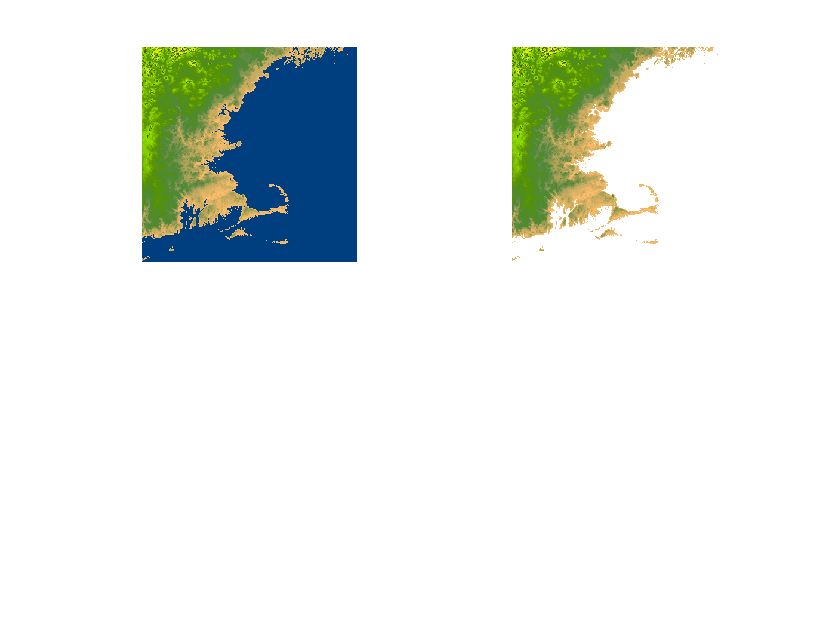

subplot(2,2,1)
I1=imshow(X,map);
X;
pnt = X==1;
map = [map; 1 1 1];
map = [map; 0 0 0];
X(pnt) = 193;
subplot(2,2,2)
I2=imshow(X,map);

# c)

This code finds all pixels that are not water and stores them in variable pct, then calculates what percentage of the image is land (everything that is not water) and prints.

pct = X~=193;
s1=sum(pct);
s2=sum(s1);
percentland=100*s2/(360*360);
fprintf("%2.3f percent of the image in pixels is land",percentland)

40.043 percent of the image in pixels is land

# d)

This code modifies the image so that the sandy areas are changed to black, and prints. I found the pixel values for sand using the data cursor.

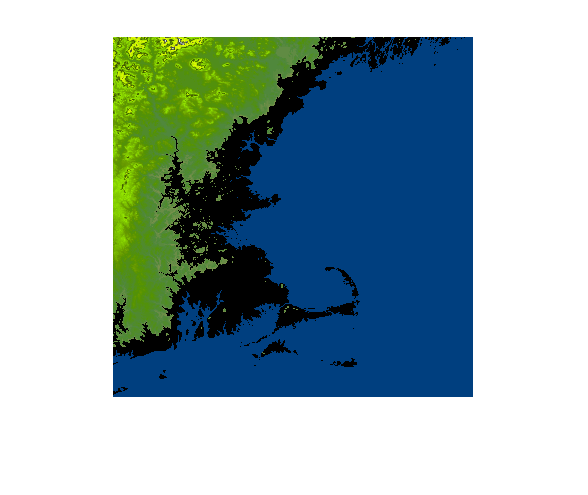

p2 = X==193;
X(p2) = 1;
p3 = (1<X & X<12);
X(p3) = 194;
subplot(1,1,1)
imshow(X,map)